% Jocelyn Espinoza - Prelim Design Code

t = 3; % 3 hours

GW_initial = 13000; %lbfs for the original XV-15 design from book

SFC = 0.6; %lb/shp hr -> assume it is the same as T53-L-138: 0.60

engine_cont_power = 1250; %shp from book!

Pa = 2*engine_cont_power; %shp

Pa_in_kw = (Pa*745.7)/1000;

W_f = SFC*Pa *t; % Weight of fuel in lbf

mass_person = 100; % IN KG given by the RFP

person_force_Newton = mass_person * 9.81; %In newtons

W_person_lbf = person_force_Newton * (1/4.448222); % Converting to lbf

w_2_people = W_person_lbf*2; % Weight of 2 ppl

payload_max = GW_initial - W_f - w_2_people; % max payload
payload_step = 5;  % lbs increment
payload_values = 0:payload_step:payload_max;  % payload values->sweep
ULF_values = zeros(size(payload_values));
GW_values  = zeros(size(payload_values));

% Loop over each payload
for i = 1:length(payload_values)
    W_payload = payload_values(i);
    W_u_l = W_f + w_2_people + W_payload;    % total useful load
    ULF_values(i) = W_u_l / GW_initial;      % re-compute load fraction
end

% Display results for payloads where useful load is between 0.3 and 0.5
ULF_rounded = round(ULF_values*1000)/1000; % round to 3 decimals
[unique_ULF, idx] = unique(ULF_rounded);
fprintf('Payload (lb)  |  Useful Load Fraction\n');

Payload (lb)  |  Useful Load Fraction


for i = 1:length(unique_ULF)
    if unique_ULF(i) >= 0.3 && unique_ULF(i) <= 0.5
        fprintf('%10.2f  |  %.3f\n', payload_values(idx(i)), unique_ULF(i));
    end
end

      0.00  |  0.380
     10.00  |  0.381
     20.00  |  0.382
     35.00  |  0.383
     45.00  |  0.384
     60.00  |  0.385
     75.00  |  0.386
     85.00  |  0.387
    100.00  |  0.388
    110.00  |  0.389
    125.00  |  0.390
    140.00  |  0.391
    150.00  |  0.392
    165.00  |  0.393
    175.00  |  0.394
    190.00  |  0.395
    205.00  |  0.396
    215.00  |  0.397
    230.00  |  0.398
    240.00  |  0.399
    255.00  |  0.400
    270.00  |  0.401
    280.00  |  0.402
    295.00  |  0.403
    305.00  |  0.404
    320.00  |  0.405
    335.00  |  0.406
    345.00  |  0.407
    360.00  |  0.408
    370.00  |  0.409
    385.00  |  0.410
    400.00  |  0.411
    410.00  |  0.412
    425.00  |  0.413
    435.00  |  0.414
    450.00  |  0.415
    465.00  |  0.416
    475.00  |  0.417
    490.00  |  0.418
    500.00  |  0.419
    515.00  |  0.420
    530.00  |  0.421
    540.00  |  0.422
    555.00  |  0.423
    565.00  |  0.424
    580.00  |  0.425
    595.00  |  0.426
    605.00  |


XV_15_original_useful_load =((1436) + w_2_people + 1148)/GW_initial; %This is the baseline useful load fraction!

Gw_target = (w_2_people + W_f + 250)/0.400;

%Calculating new

% installed power would have to be 2000 (based off Aryan's code + 10%?)

W_motors = 220.53*4 %From article with weight and power

W_motors = 882.1200


%Assume the engine stays the same so we have the same fuel weight?

W_batteries = 2887.96; %lbf

load_fraction_target = 0.4;  % Desired useful load fraction
tolerance = 5;               % lbf tolerance
increment = 5;               % lbf decrement step
max_iterations = 1000;

iteration = 0;

W_payload_last = 250;

 W_u_new = W_f + w_2_people + W_payload_last;
 GW_new  = W_u_new / load_fraction_target;

 GW_target = 13000;

 while iteration < max_iterations
    % Compute new useful load and gross weight
    W_u_new = (0.95*W_f) + w_2_people + W_payload_last;
    GW_new  = W_u_new / load_fraction_target;

    % Stop when GW_new is close to target
    if abs(GW_new - GW_target) < tolerance || W_payload_last <= 0
        break
    end

    % If GW_new is higher than target, reduce payload
    if GW_new > GW_target
        W_payload_last = max(W_payload_last - increment, 0);
    else
        % If it's too low (rare case), increase payload slightly
        W_payload_last = W_payload_last + increment;
    end

    iteration = iteration + 1;
end

% --- Display results ---
fprintf('Converged after %d iterations:\n', iteration);

Converged after 47 iterations:


fprintf('Payload = %.2f lb\n', W_payload_last);

Payload = 485.00 lb


fprintf('Gross Weight = %.2f lb\n', GW_new);

Gross Weight = 13002.69 lb


fprintf('Useful Load Fraction = %.3f\n', W_u_new / GW_new);

Useful Load Fraction = 0.400



% Pie chart!!!

W_engines = 549*2; %lbf from smithsonian website

W_generator = 290; %lbf

W_structure = 13002.69 - w_2_people - W_payload_last - (0.95*W_f) - W_batteries - W_motors - W_engines - W_generator;

W_fuel = 0.95*W_f

W_fuel = 4275

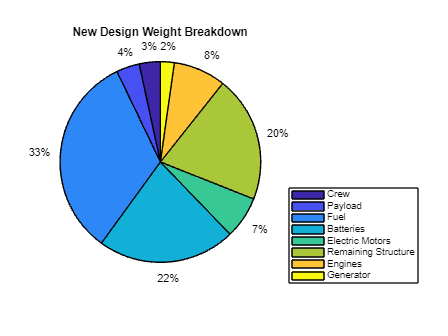


values = [w_2_people, W_payload_last, (0.95*W_f), W_batteries, W_motors, W_structure, W_engines, W_generator];
labels = ["Crew", "Payload","Fuel", "Batteries", "Electric Motors","Remaining Structure", "Engines","Generator"];
figure;
h = pie(values);

title('New Design Weight Breakdown');
legend(labels, 'Location','southeastoutside');


W_struct_total = W_generator + W_motors + W_engines + W_structure + W_batteries;